# **Ball on Plate Model - LQR**

## Model - Parameter

clearvars 

%lineares Model (kontinuirlich)
A = kron(eye(2),[0 1; 0 0]);
const = -5/7*9.81*0.3/2*3.1;
B = kron(eye(2),[0;1])*const;
C = kron(eye(2),[1 0]);
sys = ss(A,B,C,0,0,  'Name'      ,'Ball on Plate - Linear' ,...
                     'StateName' ,["xPos" "xGeschw." "yPos" "yGeschw."],...
                     'OutputName',["X Position","Y Position" ]         ,...
                     'OutputUnit',[     "m"    ,   "m"       ]         ,...
                     'InputName' ,[ "Motor A" "Motor B"      ] ,...
                     'InputUnit' ,[    "rad"    "rad"        ] ,...
                     'TimeUnit'  , 's');
%diskretes Model
dsys = c2d(sys,1/30);
clearvars -except dsys

## LQR-Regler + Vorfilter

% LQ-Regler & Vorfilter
Qk = diag([1/40 0.01 1/40 0.01]);
Rk = diag([1e-2 1e-2]);
K = dlqr(dsys.A,dsys.B,Qk,Rk);
V = ([1 0 0 0; 0 0 1 0]*((eye(4)-dsys.A+dsys.B*K)^-1)*dsys.B)^-1;
clearvars -except dsys K V

## Beobachter - Kalman Filter

%Model + Beobachter 
extend_dsys = ss(dsys.A,[dsys.B eye(4)],dsys.C,0,1/30                      ,...
                     'Name'      ,'Ball on Plate - Linear'             ,...
                     'StateName' ,["xPos" "xGeschw." "yPos" "yGeschw."],...
                     'OutputName',["X Position","Y Position" ]         ,...
                     'OutputUnit',[     "m"    ,   "m"       ]         ,...
                     'InputName' ,[ "Motor A" "Motor B" 'w1' 'w2' 'w3' 'w4'] ,...
                     'InputUnit' ,[    "rad"    "rad"   ' '  ' '   ' ' ' '  ],...
                     'TimeUnit'  , 's');

[kf_dsys,L] = kalman(extend_dsys,0.2*eye(4),eye(2)*0.1,0);

clearvars -except dsys K V L

x0_hat = [0 0 0 0];

%Simulink Simulation
sim_data = sim("Model","StartTime","0","StopTime","10");

Error due to multiple causes.

Caused by:
    Error using StartUp
    When parameter 'InputProcessing' is set to 'Elements as channels (sample based)' and data input signal is 2-D or N-D signals, the dimension of initial condition should be scalar or equal to the dimension of data input if it is unit delay.
    Error using StartUp
    Error in port widths or dimensions. 'Output Port 1' of 'Model/Beobachter/Sum1' is a [4x1] matrix.


t = sim_data.get("tout");
y = sim_data.get("logsout").get("y_out").Values.Data;
y_kf = sim_data.get("logsout").get("y_kf").Values.Data;
w = sim_data.get("logsout").get("Führungsgröße").Values.Data.*ones(size(t));
u = sim_data.get("logsout").get("Stellgröße").Values.Data;


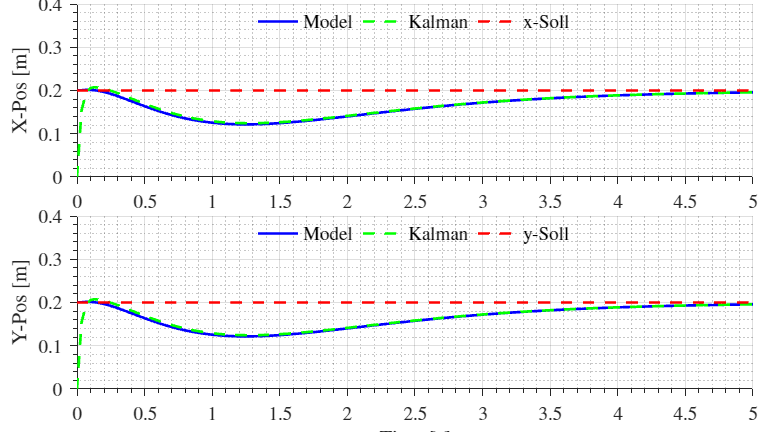

drawOutPutData(t,y,y_kf,w)

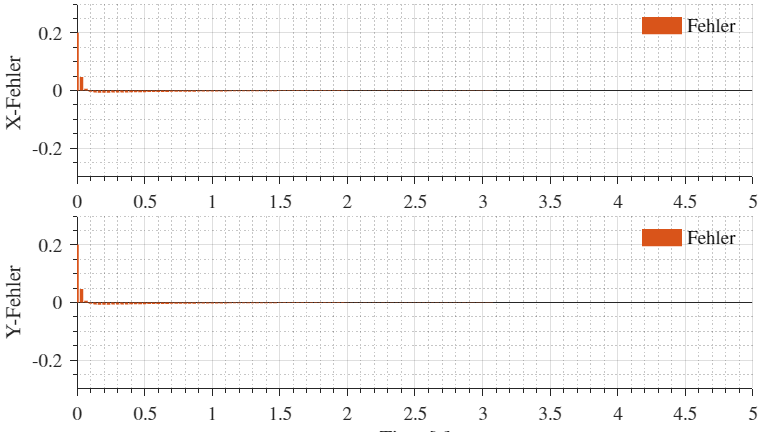

drawError(t,y-y_kf)

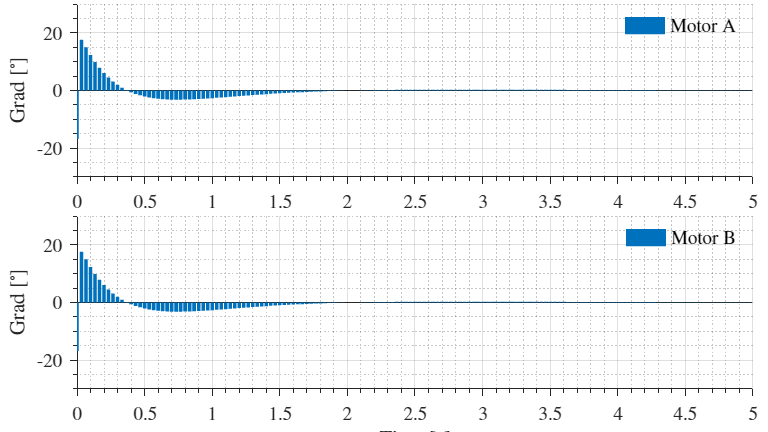

drawInPutData(t,u)

function drawOutPutData(t,y,y_kf,w)
    clf
    figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
     
    % Create axes
    axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
                 'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
    hold(axes1,'on');
    % Create plot
    plot(t,y(:,1),'DisplayName','Model','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
    plot(t,y_kf(:,1),'DisplayName','Kalman','LineWidth',2,'LineStyle','--','Color',[0 1 0]);
    if ~isempty(w)
        plot(t,w(:,1),'DisplayName','x-Soll','LineWidth',2,'LineStyle','--','Color',[1 0 0]);
        ylim(axes1,[0 0.4]);
    end
    
    xlim([0 max(t)]);
    
    % Create ylabel
    ylabel('X-Pos [m]','FontSize',16,'Interpreter','latex');
     
    % Create xlabel
    xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
    'HorizontalAlignment','center',...
    'FontSize',16,...
    'Interpreter','latex',Visible='off');
     
    % Uncomment the following line to preserve the Y-limits of the axes
    % Create legend
    legend1 = legend(axes1,'show');
    set(legend1,'Orientation','horizontal','Interpreter','latex',...
    'FontAngle','italic',...
    'FontSize',14,...
    'EdgeColor','none','Color','none','Location','best');
    
    
    hold(axes1,'off');
    % Create axes
    axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
                 'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
    
    hold(axes2,'on');                         
    
    % Create plot
    plot(t,y(:,2),'DisplayName','Model','LineWidth',2,'LineStyle','-','Color',[0 0 1]);
    plot(t,y_kf(:,2),'DisplayName','Kalman','LineWidth',2,'LineStyle','--','Color',[0 1 0]);

    if ~isempty(w)
        plot(t,w(:,2),'DisplayName','y-Soll','LineWidth',2,'LineStyle','--','Color',[1 0 0]);
        ylim(axes2,[0 0.4]);
    end 
    
    xlim([0 max(t)]);
    
    % Create ylabel
    ylabel('Y-Pos [m]','FontSize',16,'Interpreter','latex');
    
    
    % Create xlabel
    xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
    'HorizontalAlignment','center',...
    'FontSize',16,...
    'Interpreter','latex');
    
    legend2 = legend(axes2,'show');
    set(legend2,'Orientation','horizontal','Interpreter','latex',...
    'FontAngle','italic',...
    'FontSize',14,...
    'EdgeColor','none','Color','none','Location','best');
     
    hold(axes2,'off');
end

function drawError(t,e)
    clf
    figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
     
    % Create axes
    axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
                 'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
    hold(axes1,'on');
    % Create plot
    bar(t,e(:,1),'DisplayName','Fehler','FaceColor',[0.85 0.33 0.10]);
    
    ylim(axes1,[-0.3 0.3]);
    xlim([0 max(t)]);
    
    % Create ylabel
    ylabel('X-Fehler ','FontSize',16,'Interpreter','latex');
     
    % Create xlabel
    xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
    'HorizontalAlignment','center',...
    'FontSize',16,...
    'Interpreter','latex',Visible='off');
     
    % Uncomment the following line to preserve the Y-limits of the axes
    % Create legend
    legend1 = legend(axes1,'show');
    set(legend1,'Orientation','horizontal','Interpreter','latex',...
    'FontAngle','italic',...
    'FontSize',14,...
    'EdgeColor','none','Color','none','Location','northeast');
    
    
    hold(axes1,'off');
    % Create axes
    axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
                 'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
    
    hold(axes2,'on');                         
    
    % Create plot
    bar(t,e(:,2),'DisplayName','Fehler','FaceColor',[0.85 0.33 0.10]);
     
    ylim(axes2,[-0.3 0.3]);
    xlim([0 max(t)]);
    
    % Create ylabel
    ylabel('Y-Fehler','FontSize',16,'Interpreter','latex');
    
    
    % Create xlabel
    xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
    'HorizontalAlignment','center',...
    'FontSize',16,...
    'Interpreter','latex');
    
    legend2 = legend(axes2,'show');
    set(legend2,'Orientation','horizontal','Interpreter','latex',...
    'FontAngle','italic',...
    'FontSize',14,...
    'EdgeColor','none','Color','none','Location','northeast');
     
    hold(axes2,'off');
end

function drawInPutData(t,u)
    clf
    figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],'Units','normalized','Position',[0.1 0.1 0.4 0.4]);
     
    % Create axes
    axes1 = axes('Parent',figure1,'Position',[0.1 0.59 0.88 0.4],'FontSize',14, ...
                 'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
    hold(axes1,'on');
    % Create plot
    bar(t,rad2deg(u(:,1)),'DisplayName','Motor A');
    
    ylim(axes1,[-30 30]);
    xlim([0 max(t)]);
    
    % Create ylabel
    ylabel('Grad [$^\circ$]','FontSize',16,'Interpreter','latex');
     
    % Create xlabel
    xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
    'HorizontalAlignment','center',...
    'FontSize',16,...
    'Interpreter','latex',Visible='off');
     
    % Uncomment the following line to preserve the Y-limits of the axes
    % Create legend
    legend1 = legend(axes1,'show');
    set(legend1,'Orientation','horizontal','Interpreter','latex',...
    'FontAngle','italic',...
    'FontSize',14,...
    'EdgeColor','none','Color','none','Location','northeast');
    
    
    hold(axes1,'off');
    % Create axes
    axes2 = axes('Parent',figure1,'Position',[0.1 0.1 0.88 0.4],'FontSize',14, ...
                 'TickLabelInterpreter','latex','XMinorGrid','on','YMinorGrid','on',XGrid='on',YGrid='on',TickDir='out',XMinorTick='on',YMinorTick='on');
    
    hold(axes2,'on');                         
    
    % Create plot
    bar(t,rad2deg(u(:,2)),'DisplayName','Motor B');
 
    ylim(axes2,[-30 30]);
    xlim([0 max(t)]);
    
    % Create ylabel
    ylabel('Grad [$^\circ$]','FontSize',16,'Interpreter','latex');
    
    
    % Create xlabel
    xlabel('Time [s]','Units','normalized','VerticalAlignment','cap',...
    'HorizontalAlignment','center',...
    'FontSize',16,...
    'Interpreter','latex');
    
    legend2 = legend(axes2,'show');
    set(legend2,'Orientation','horizontal','Interpreter','latex',...
    'FontAngle','italic',...
    'FontSize',14,...
    'EdgeColor','none','Color','none','Location','northeast');
     
    hold(axes2,'off');
end
